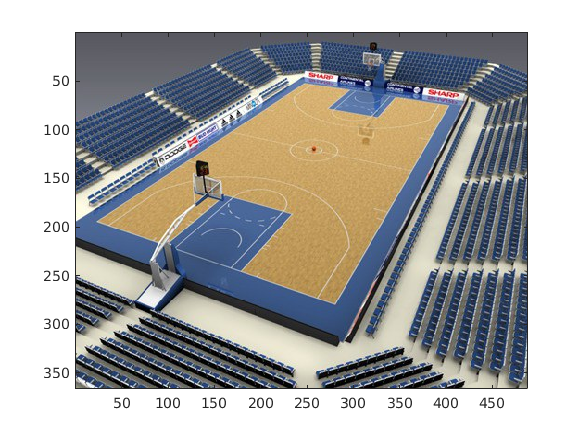

clear all;
%format long;

%Problem1

%Q1
img = imread('basketball-court.ppm');
image(img);


% [xi,yi] = getpts;

% orgin pts
xi = [24.7920;247.1991;282.8274;409.1460];
yi = [197.3792;53.4466;285.7949;79.1489];
%target pts
Xp = [0.; 940.; 0.; 940.];
Yp = [0.; 0.; 500.; 500.];
%copy orgin pts
xi_orgin = xi;
yi_orgin = yi;
Xp_orgin = Xp;
Yp_orgin = Yp;

% i normalized
%
w = 488;
h = 366;
Tnorm = inv([w+h,0,w/2;0,w+h,h/2;0,0,1]);
for i = 1:4
    tp = Tnorm*[xi(i);yi(i);1];
    xi(i) =tp(1);
    yi(i) =tp(2);
end

wp = 940;
hp = 500;
Tnorm_p = inv([wp+hp,0,wp/2;0,wp+hp,hp/2;0,0,1]);
for i = 1:4
    tp = Tnorm_p*[Xp(i);Yp(i);1] ;
    Xp(i) =tp(1);
    Yp(i) =tp(2);
end


%}

%ii DLT

Ai = zeros(2*4, 9);

for i = 1:4
    Ai(i*2-1,:) = [0,0,0, -xi(i),-yi(i),-1,Yp(i)*xi(i),Yp(i)*yi(i),Yp(i)];
    Ai(i*2,:) = [xi(i),yi(i),1,0,0,0,-xi(i)*Xp(i),-yi(i)*Xp(i),-Xp(i)];
end;


[U,S,V] = svd(Ai);

h = V(:,9);

Hi = reshape(h,3,3);
Hi = Hi';

%iii denormlized
Hp =  inv(Tnorm_p)*Hi*Tnorm ;
%

%verify result
result = zeros(4,3);
pts = zeros(4,2);

for i = 1:4
    result(i,:) = Hp*[xi_orgin(i),yi_orgin(i),1]';
    pts(i,:) = [result(i,1)/result(i,3),result(i,2)/result(i,3)];
end;

pts

pts =     0.0000    0.0000
  940.0000    0.0000
    0.0000  500.0000
  940.0000  500.0000


Hi

Hi =    -0.1281    0.5905    0.0419
   -0.2465   -0.2658   -0.0138
   -0.0001   -0.6632   -0.2483


Hp

Hp =    -0.2161    0.6306 -119.1176
   -0.4157   -0.6424  137.1025
   -0.0000   -0.0008   -0.1061



%Q2
%
new_img = zeros(500,940,3);
Hinv = inv(Hp)

Hinv =    -1.6789   -1.5327  -95.5600
    0.4244   -0.2203 -760.7920
   -0.0031    0.0016   -3.8545


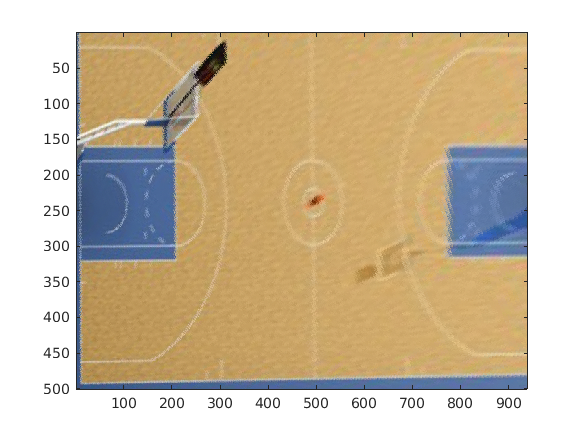

for i = 0:939
    for j = 0:499
        %get mapping pts
        p = [i j 1];
        p_map = Hinv*p';
        pts_map = [p_map(1)/p_map(3),p_map(2)/p_map(3)];
        
        %
        ii = fix(pts_map(1));
        jj = fix(pts_map(2));
        
        %
        a = pts_map(1) - ii;
        b = pts_map(2) - jj;
        
        %2d interpolation
        target_pts = (1-a) * (1-b) * img(jj,ii,:) + a * (1-b) * img(jj+1,ii,:) + a * b * img(jj+1,ii+1,:) + (1-a) * b * img(jj,ii+1,:);
           
        new_img(j+1,i+1,:) = target_pts(:);
    end
end
%show new image
image(new_img/256);

%}
